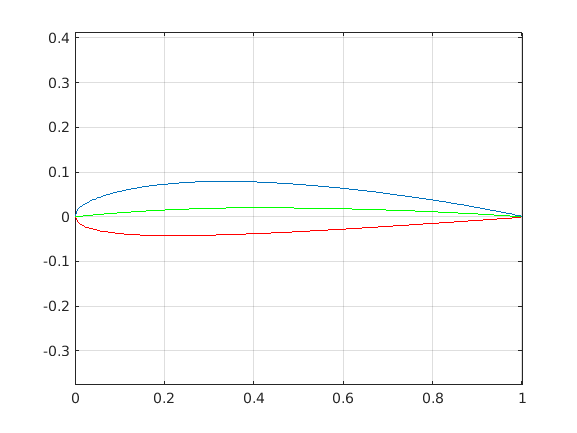

c=1; %chord length
s=num2str(2412);
NACA=s; %4 digits
d1=str2double(s(1)); % pulls the first digit out of the scalar
d2=str2double(s(2));% pulls the second digit out of the scalar
d34=str2double(s(3:4)); % pulls the third and fourth digit out of the scalar
m=d1/100;
p=d2/10;
t=d34/100;
x=linspace(0, c, 250);
yt =5*t*c*(.2969*(sqrt(x/c))+-.1260*(x/c)+-.3516*(x/c).^2+.2843*(x/c).^3+-.1015*(x/c).^4);
for k = 1:length(x)
      if x(k) <= p*c
          yc(k)=m*(x(k)/p^2)*(2*p-(x(k)/c));
          dx(k)=(2*m)/p^2*(p-(x(k)/c));
      elseif x(k) > p*c
          yc(k)=m*((c-x(k))/(1-p)^2)*(1+(x(k)/c)-(2*p));
          dx(k)=((2*m)/(1-p)^2)*(p-(x(k)/c));
      end
      %upper and lower limits of the airfoil (xu,yu) ; (xl,yl)
      theta=atan(dx(k));
      xu(k)=x(k)-yt(k)*sin(theta);
      yu(k)=yc(k)+yt(k)*cos(theta);
      xl(k)=x(k)+yt(k)*sin(theta);
      yl(k)=yc(k)-yt(k)*cos(theta);
  end
  %plot of airfoil
  plot(xu,yu)
  hold on
  plot(xl,yl,'r')
  plot(x,yc,'g')
  axis equal
  grid

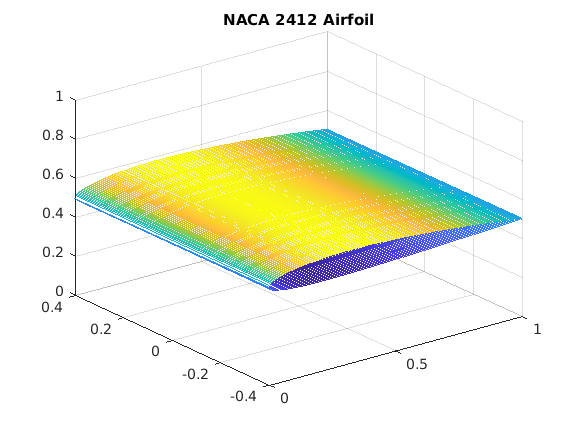

figure(2)
hu = mesh([xu; xu], [yu; yu], [zeros(size(xu)); ones(size(xu))]);     % Upper Half Of 3-D Wing Section
hold on
hl = mesh([xl; xl], [yl; yl], [zeros(size(xl)); ones(size(xl))]);     % Lower Half Of 3-D Wing Section
hold off
grid on
axis([0  1    -0.4  0.4    0  1])
rotate(hu,[1 0 0], 90)
rotate(hl,[1 0 0], 90)
title('NACA 2412 Airfoil')